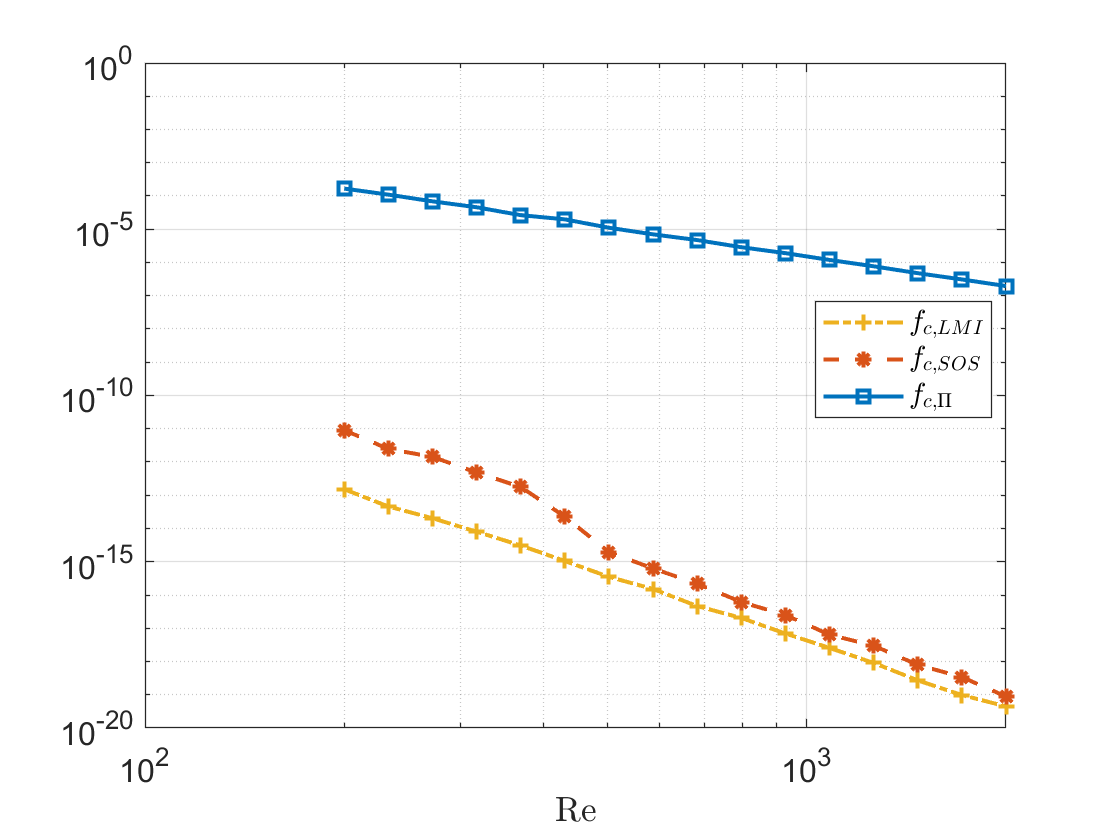

    % Create a new figure
line_width = 1.5;
colors = lines(16);
line_styles = {"-","--","-.",":"};
markers = {'+', 'o', '*', 'x', 's', 'd', '^', 'v', '>', '<', 'p', 'h'};
line_width = 1.5;
figure;
max_forcing_bi = max(forcing_bi, [],2); 
% Plot 3: Re_list vs forcing_LMI
% forcing_LMI_values = cellfun(@(x) norm(x, 'fro'), forcing_LMI); % Frobenius norm of forcing_LMI
loglog(Re_list, u_upper_bound_max(:,:), line_styles{3}, 'LineWidth', line_width, 'Color', colors(3, :),'Marker', markers{1});

% Retain the current plot and add the next plot
hold on;
loglog(Re_list, u_upper_bound_max_SOS(:,:), line_styles{2}, 'LineWidth', line_width, 'Color', colors(2, :),'Marker', markers{3});
% Plot 4: Re_list vs local_forcing_amp
% max_forcing_bi_e_7 = max(forcing_bi_e_7, [], 2); % 16x1 column vector 
% % loglog(Re_list, forcing_bi(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :),'Marker', markers{2});
% loglog(Re_list, max_forcing_bi_e_7(:, :), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :),'Marker', markers{1});
% max_forcing_bi_e_8 = max(forcing_bi_e_8, [], 2); % 16x1 column vector 
% loglog(Re_list, forcing_bi(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :),'Marker', markers{2});
% loglog(Re_list, forcing_bi_e_8_no(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :),'Marker', markers{2});
% % max_forcing_bi_e_9 = max(forcing_bi_e_9, [], 2); % 16x1 column vector 
% % loglog(Re_list, forcing_bi(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :),'Marker', markers{2});
% loglog(Re_list, forcing_bi_e_9_no(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(5, :),'Marker', markers{4});
% % max_forcing_bi_e_10 = max(forcing_bi_e_10, [], 2); % 16x1 column vector 
% % loglog(Re_list, forcing_bi(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :),'Marker', markers{2});
% loglog(Re_list, forcing_bi_e_10_no(:, :), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :),'Marker', markers{5});
loglog(Re_list, max_forcing_bi(:, :), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :),'Marker', markers{5});

% Add titles, labels, and legend
xlabel('Re', 'FontSize', 12,'Interpreter', 'latex');
xlim([1e2, 2000]);  
legend('$f_{c,LMI}$','$f_{c,SOS}$','$f_{c,\Pi}$','Interpreter', 'latex');
% legend('$f_{c,LMI}$','$f_{c,SOS}$','$f_{\hat c,10^{-8}}$','$f_{\hat c,10^{-9}}$','$f_{\hat c,10^{-10}}$', 'f','Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 12);

% Release the hold to avoid further plots being added to this figure
hold off;

legend("Position",[0.73899,0.49841,0.14821,0.14048])

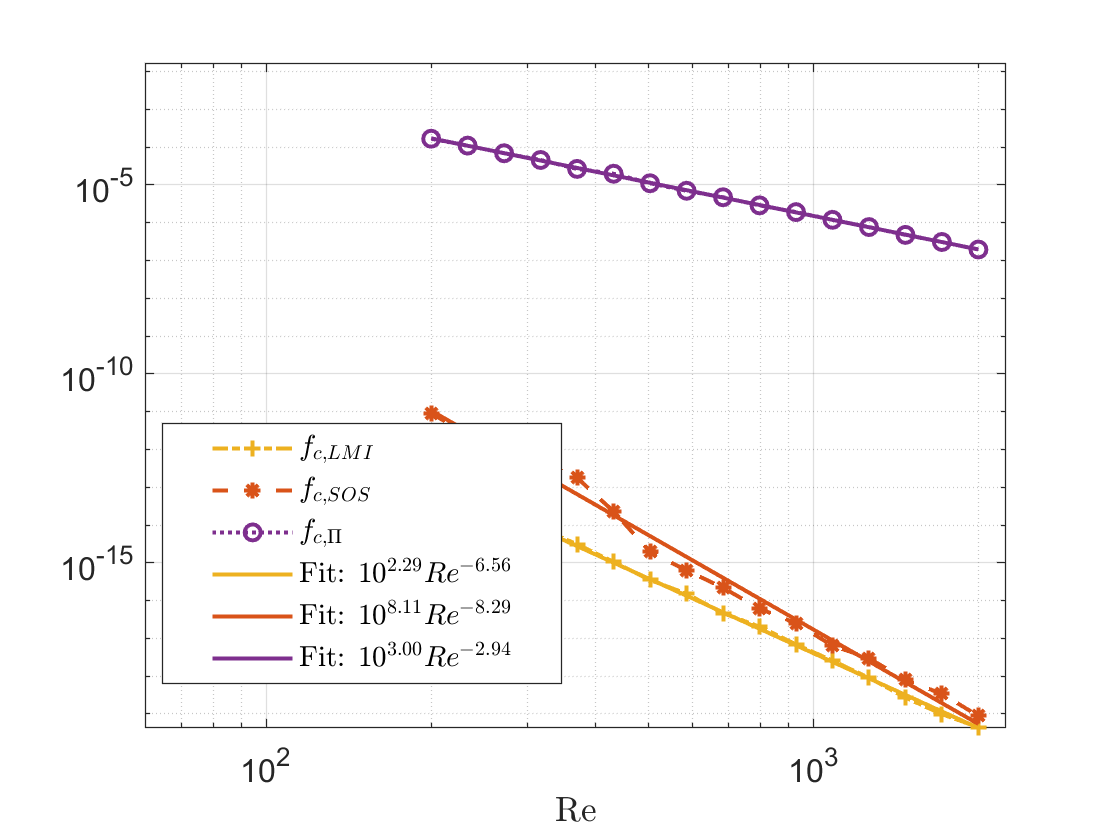




figure;

% Plot original data with DisplayNames
loglog(Re_list, u_upper_bound_max, line_styles{3}, 'LineWidth', line_width, ...
    'Color', colors(3, :), 'Marker', markers{1}, 'DisplayName', '$f_{c,LMI}$');
hold on;
loglog(Re_list, u_upper_bound_max_SOS, line_styles{2}, 'LineWidth', line_width, ...
    'Color', colors(2, :), 'Marker', markers{3}, 'DisplayName', '$f_{c,SOS}$');
loglog(Re_list, max_forcing_bi, line_styles{4}, 'LineWidth', line_width, ...
    'Color', colors(4, :), 'Marker', markers{2}, 'DisplayName', '$f_{c,\Pi}$');

% Compute log values for fitting
log_Re = log10(Re_list(:));

% Fit for u_upper_bound_max
log_data1 = log10(u_upper_bound_max(:));
coeffs1 = polyfit(log_Re, log_data1, 1);
fit_line1 = 10.^polyval(coeffs1, log_Re);
loglog(Re_list, fit_line1, '-', 'LineWidth', line_width, 'Color', colors(3, :), ...
    'DisplayName', sprintf('Fit: $10^{%.2f} Re^{%.2f}$', coeffs1(2), coeffs1(1)));

% Fit for u_upper_bound_max_SOS
log_data2 = log10(u_upper_bound_max_SOS(:));
coeffs2 = polyfit(log_Re, log_data2, 1);
fit_line2 = 10.^polyval(coeffs2, log_Re);
loglog(Re_list, fit_line2, '-', 'LineWidth', line_width, 'Color', colors(2, :), ...
    'DisplayName', sprintf('Fit: $10^{%.2f} Re^{%.2f}$', coeffs2(2), coeffs2(1)));

% Fit for max_forcing_bi
log_data3 = log10(max_forcing_bi(:));
coeffs3 = polyfit(log_Re, log_data3, 1);
fit_line3 = 10.^polyval(coeffs3, log_Re);
loglog(Re_list, fit_line3, '-', 'LineWidth', line_width, 'Color', colors(4, :), ...
    'DisplayName', sprintf('Fit: $10^{%.2f} Re^{%.2f}$', coeffs3(2), coeffs3(1)));

hold off;

% Labels and legend
xlabel('Re', 'FontSize', 10, 'Interpreter', 'latex');
xlim([1e2, 2000]);
% legend('Interpreter', 'latex', 'Location', 'best', 'FontSize', 10);
legend('Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 12);

xlim([60 2246])
ylim([0.0000 0.0169])
legend("Position",[0.14689,0.17975,0.35819,0.31262])


% Display scaling exponents and intercepts
disp('For f_{c,LMI}:');

For f_{c,LMI}:


disp(['Scaling exponent (σ): ', num2str(coeffs1(1))]);

Scaling exponent (σ): -6.5635


disp(['Intercept (A): ', num2str(coeffs1(2))]);

Intercept (A): 2.2939



disp('For f_{c,SOS}:');

For f_{c,SOS}:


disp(['Scaling exponent (σ): ', num2str(coeffs2(1))]);

Scaling exponent (σ): -8.2921


disp(['Intercept (A): ', num2str(coeffs2(2))]);

Intercept (A): 8.1055



disp('For f_c:');

For f_c:


disp(['Scaling exponent (σ): ', num2str(coeffs3(1))]);

Scaling exponent (σ): -2.9408


disp(['Intercept (A): ', num2str(coeffs3(2))]);

Intercept (A): 3.0009







figure;

% Plot 3: Re_list vs forcing_LMI
% forcing_LMI_values = cellfun(@(x) norm(x, 'fro'), forcing_LMI); % Frobenius norm of forcing_LMI
% max_forcing_bi_e_8_no = max(forcing_bi_e_8_no, [], 2); % 16x1 column vector 
% loglog(Re_list, forcing_bi(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :),'Marker', markers{2});
loglog(Re_list, forcing_bi_e_8_no(:, :), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :),'Marker', markers{1});

Unrecognized function or variable 'forcing_bi_e_8_no'.


% Retain the current plot and add the next plot
hold on;
% max_forcing_bi_e_9_no = max(forcing_bi_e_9_no, [], 2); % 16x1 column vector 
% loglog(Re_list, forcing_bi(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :),'Marker', markers{2});
loglog(Re_list, forcing_bi_e_9_no(:, :), line_styles{2}, 'LineWidth', line_width, 'Color', colors(1, :),'Marker', markers{2});
% max_forcing_bi_e_10_no = max(forcing_bi_e_10_no, [], 2); % 16x1 column vector 
% loglog(Re_list, forcing_bi(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :),'Marker', markers{2});
loglog(Re_list, forcing_bi_e_10_no(:, :), line_styles{3}, 'LineWidth', line_width, 'Color', colors(1, :),'Marker', markers{3});
% Plot 4: Re_list vs local_forcing_amp
% max_forcing_bi_e_7 = max(forcing_bi_e_7, [], 2); % 16x1 column vector 
% % loglog(Re_list, forcing_bi(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :),'Marker', markers{2});
% loglog(Re_list, max_forcing_bi_e_7(:, :), line_styles{1}, 'LineWidth', line_width, 'Color', colors(1, :),'Marker', markers{1});
max_forcing_bi_e_8 = max(forcing_bi_e_8, [], 2); % 16x1 column vector 
% loglog(Re_list, forcing_bi(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :),'Marker', markers{2});
loglog(Re_list, max_forcing_bi_e_8(:, :), line_styles{1}, 'LineWidth', line_width, 'Color', colors(2, :),'Marker', markers{4});
max_forcing_bi_e_9 = max(forcing_bi_e_9, [], 2); % 16x1 column vector 
% loglog(Re_list, forcing_bi(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :),'Marker', markers{2});
loglog(Re_list, max_forcing_bi_e_9(:, :), line_styles{2}, 'LineWidth', line_width, 'Color', colors(2, :),'Marker', markers{5});
max_forcing_bi_e_10 = max(forcing_bi_e_10, [], 2); % 16x1 column vector 
% loglog(Re_list, forcing_bi(:, :), line_styles{4}, 'LineWidth', line_width, 'Color', colors(4, :),'Marker', markers{2});
loglog(Re_list, max_forcing_bi_e_10(:, :), line_styles{3}, 'LineWidth', line_width, 'Color', colors(2, :),'Marker', markers{6});

% Add titles, labels, and legend
xlabel('Re', 'FontSize', 12,'Interpreter', 'latex');
xlim([1e2, 2000]);  
legend('$f_{\hat c,10^{-8}}$','$f_{\hat c,10^{-9}}$','$f_{\hat c,10^{-10}}$','$f_{c,10^{-8}}$','$f_{c,10^{-9}}$','$f_{c,10^{-10}}$','Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 12);

% Release the hold to avoid further plots being added to this figure
hold off;

legend("Position",[0.73899,0.49841,0.14821,0.14048])

